clear
close all
% delete(gcp('nocreate'))
% parpool ('processes',4)

tic
% Launch a file dialog box to select a file
[name, path] = uigetfile('*.nwb', 'Select a File');

% Check if the user canceled the file selection
if isequal(name, 0)
    disp('User canceled file selection');
else
    % Display the selected file's full path
    disp(['Selected file: ' fullfile(path, name)]);
end

Selected file: /Users/platel/Desktop/exp/aurelie/to analyse/444118/P2M_444118_220914_plane1_2023_05_04.08-52-24.nwb



% filename= '/Users/platel/Desktop/exp/aurelie/444175_new/P2M_444175_221125_plane1_2023_01_09.09-19-40.nwb';
% path='/Users/platel/Desktop/exp/aurelie/444175_new/';
% name='P2M_444175_221125_plane1_2023_01_09.09-19-40.nwb';

%filename='/Volumes/Crucial-JC/411582/P2M_411582_230320_plane1_2023_04_05.17-57-09.nwb';
% path='/Users/platel/Desktop/exp/aurelie/to analyse/444152/clean/';
% name='P2M_444152_221129_plane1_2023_01_12.10-12-20.nwb';

PathSave='/Users/platel/Desktop/exp/analysis/';
filename=[path name];
daytime = datestr(now,'yy_mm_dd_HH_MM_SS');
namefull=[PathSave daytime name '/'];
mkdir (namefull)    % make folder for saving analysis
disp(['make new folder ' namefull])

make new folder /Users/platel/Desktop/exp/analysis/23_10_06_11_53_01P2M_444118_220914_plane1_2023_05_04.08-52-24.nwb/


median normalization
bleaching correction
sgolayfilter
Ncells= 775
Sum transient: 132617
sce_n_cells_threshold: 19
nSCE: 413
Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 1 4 5 18 20 22 23 27 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 1 4 5 18 20 22 23 27 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to parallel pool with 8 workers.
nClusters: 14


nClustersOK: 8
nSCEOK: 228


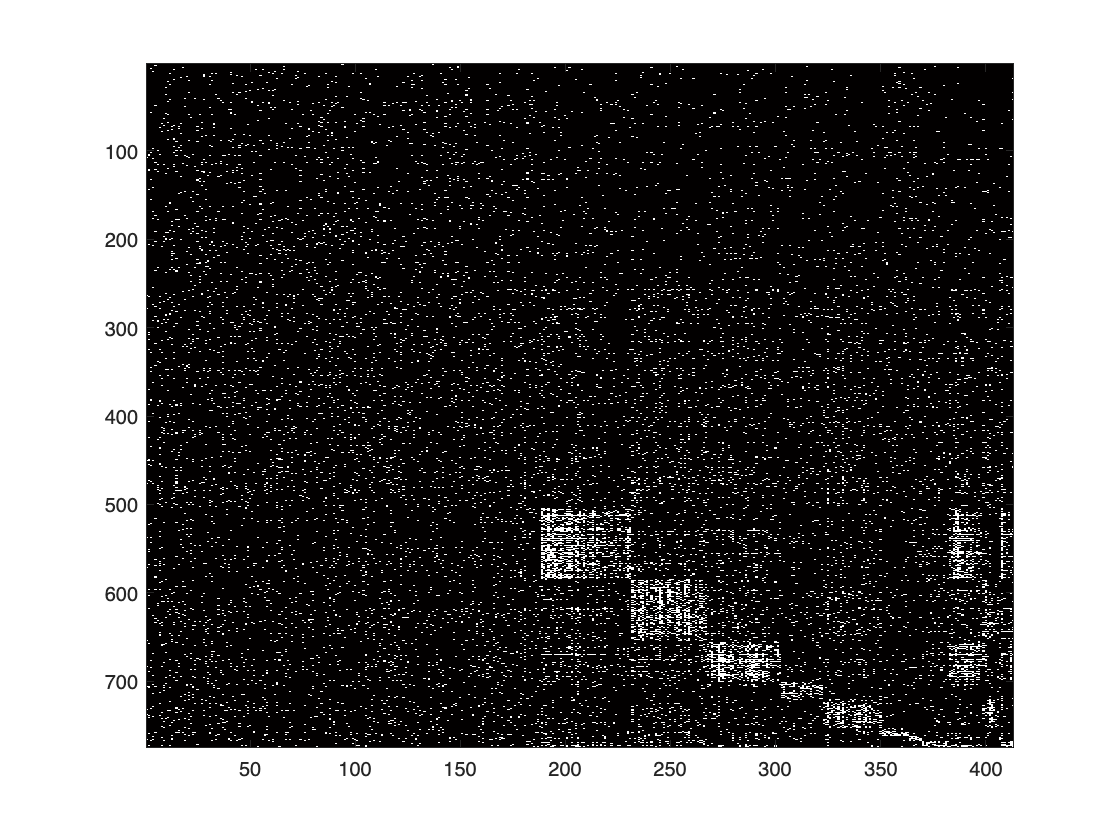

Elapsed time is 648.407520 seconds.



openingnwb
assembly_SCE5

%plotassembly


brainbowassemblies2023_09_26
%distance_calculation

% catch exception
%     disp(['An error occurred in: ' filename]);
%     disp(exception.message);  % Display the error message
%     disp('but analysis continue ;)')
% end

% end